# Asesoria

### Metodos Numericos

#### 2022-2S : 02/09/2022

Función a analizar: $\frac{5}{x^2 }+2$, $I=\left\lbrack 2\ldotp 5\;,3\right\rbrack$

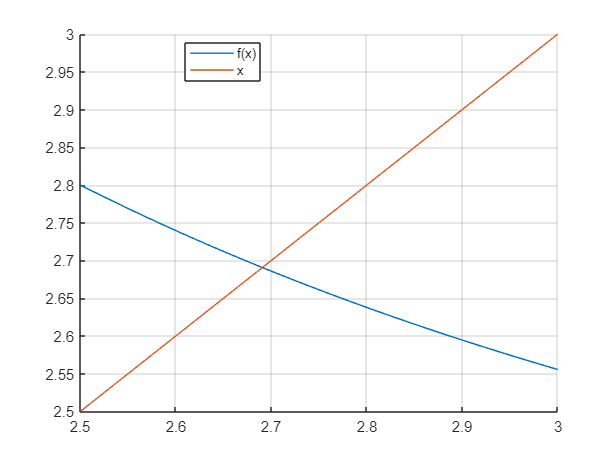

clear
syms f(x)

f(x) = 5 / x^2 + 2;

clf('reset')
hold on
fplot(f, [2.5, 3], 'DisplayName', 'f(x)')
fplot(x, [2.5, 3], 'DisplayName', 'x')
legend('Location', 'best')
grid on
hold off

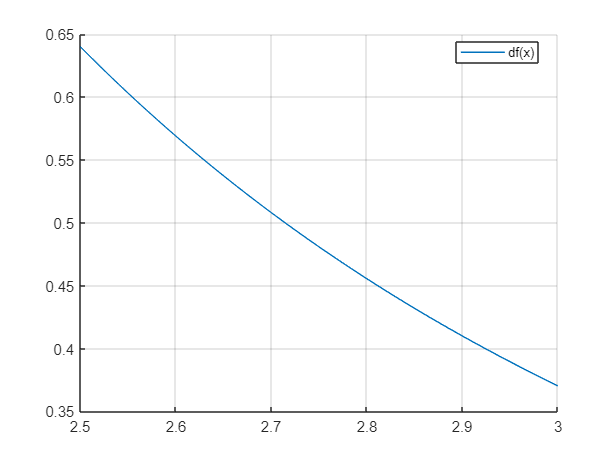

df(x) = abs(diff(f, x));
clf('reset')
hold on
fplot(df, [2.5, 3], 'DisplayName', 'df(x)')
legend('Location', 'best')
grid on
hold off

k = eval(df(2.5))

k = 0.6400

tol = 1e-10;
a = 2.5; b = 3;
p0 = (a + b) / 2;

syms n

solve(tol == k^n * max([b - p0, p0 - a]), n, 'Real', true)

$$ans = -\frac{2\,\log\left(50000\right)}{\log\left(\frac{16}{25}\right)}$$

eval(ans), n = ceil(ans)

ans = 48.4880

n = 49

syms m

solve(tol == k^m / (1 - k) * abs(f(p0) - p0), m, 'Real', true)

$$ans = -\frac{\log\left(\frac{2687500000000}{1089}\right)}{\log\left(\frac{16}{25}\right)}$$

eval(ans), n = ceil(ans)

ans = 48.4590

n = 49

clear
syms f(x, y, z)

f(x, y, z) = [exp(-x - y)*cos(3*z * y ^2), cos(x^2 * y) - y^2, log(x+y)*cos(5*x)/cos(z)]

$$f(x, y, z) = \left(\begin{array}{ccc} \cos\left(3\,y^{2}\,z\right)\,{\mathrm{e}}^{-x-y} & \cos\left(x^{2}\,y\right)-y^{2} & \frac{\cos\left(5\,x\right)\,\log\left(x+y\right)}{\cos\left(z\right)} \end{array}\right)$$

J(x, y, z) = jacobian(f)

$$J(x, y, z) = \begin{array}{l} \left(\begin{array}{ccc} -\sigma_{3} & -\sigma_{3}-6\,y\,z\,\sin\left(\sigma_{4}\right)\,{\mathrm{e}}^{-x-y} & -3\,y^{2}\,\sin\left(\sigma_{4}\right)\,{\mathrm{e}}^{-x-y}\\ -2\,x\,y\,\sigma_{2} & -2\,y-x^{2}\,\sigma_{2} & 0\\ \sigma_{1}-\frac{5\,\sin\left(5\,x\right)\,\log\left(x+y\right)}{\cos\left(z\right)} & \sigma_{1} & \frac{\cos\left(5\,x\right)\,\log\left(x+y\right)\,\sin\left(z\right)}{{\cos\left(z\right)}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(5\,x\right)}{\cos\left(z\right)\,\left(x+y\right)}\\ \sigma_{2}=\sin\left(x^{2}\,y\right)\\ \sigma_{3}=\cos\left(\sigma_{4}\right)\,{\mathrm{e}}^{-x-y}\\ \sigma_{4}=3\,y^{2}\,z \end{array}$$

J = matlabFunction(J)

J = function_handle with value:
    @(x,y,z)reshape([-cos(y.^2.*z.*3.0).*exp(-x-y),x.*y.*sin(x.^2.*y).*-2.0,cos(x.*5.0)./(cos(z).*(x+y))-(sin(x.*5.0).*log(x+y).*5.0)./cos(z),-cos(y.^2.*z.*3.0).*exp(-x-y)-y.*z.*sin(y.^2.*z.*3.0).*exp(-x-y).*6.0,y.*-2.0-x.^2.*sin(x.^2.*y),cos(x.*5.0)./(cos(z).*(x+y)),y.^2.*sin(y.^2.*z.*3.0).*exp(-x-y).*-3.0,0.0,cos(x.*5.0).*log(x+y).*1.0./cos(z).^2.*sin(z)],[3,3])


J(1, 2, 3)

ans =     0.0064    1.7840    0.5925
   -3.6372   -4.9093         0
   -5.4162   -0.0955    0.0449


J = @(X) J(X(1), X(2), X(3)); % Vectorización

J([1, 2, 3])

ans =     0.0064    1.7840    0.5925
   -3.6372   -4.9093         0
   -5.4162   -0.0955    0.0449


clear
syms f(x)

f(x) = x^3 - 5

$$f(x) = x^{3}-5$$

vector = [1 3 5 6]

vector =      1     3     5     6


eval(f(vector))

ans =     -4    22   120   211


f([1 3 5 6])

$$ans = \left(\begin{array}{cccc} -4 & 22 & 120 & 211 \end{array}\right)$$

df(x) = diff(f, x)

$$df(x) = 3\,x^{2}$$

f = matlabFunction(f)

f = function_handle with value:
    @(x)x.^3-5.0


clear
syms x

f = @(x) x.^3 - 5;
vector = [1 3 5 6];

f(vector)

ans =     -4    22   120   211


df = @(y) subs(diff(f, x), x, y)

df = function_handle with value:
    @(y)subs(diff(f,x),x,y)


df(3)

$$ans = 27$$

clear

A = [0 0 1; 2 3 4; 1 4 3]

A =      0     0     1
     2     3     4
     1     4     3


x = 1:4;
norm(A)

ans = 7.3491

clear
x = linspace(0, 10, 100);
f = x.^2 ./ (x.^2 - 1);

f =          0   -0.0103   -0.0425   -0.1011   -0.1951   -0.3424   -0.5806   -0.9998   -1.8818   -4.7619   50.2513    5.2632    3.1311    2.3806    2.0002    1.7718    1.6204    1.5132    1.4337    1.3727    1.3245    1.2858    1.2539    1.2274    1.2050    1.1860    1.1696    1.1553    1.1429    1.1319    1.1222    1.1136    1.1058    1.0989    1.0926    1.0870    1.0818    1.0771    1.0728    1.0689    1.0653    1.0619    1.0588    1.0560    1.0533    1.0509    1.0486    1.0464    1.0444    1.0426


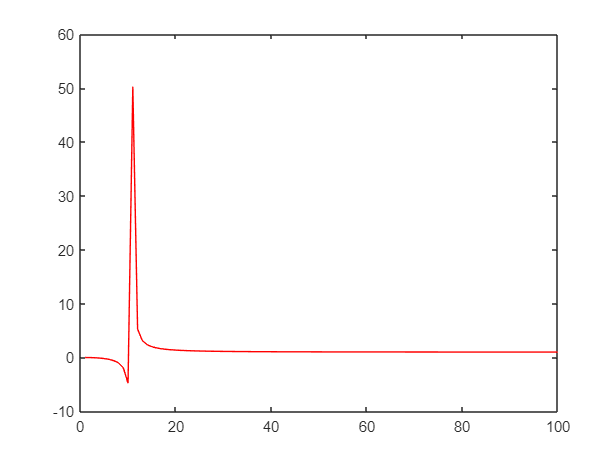

plot(f, 'r')

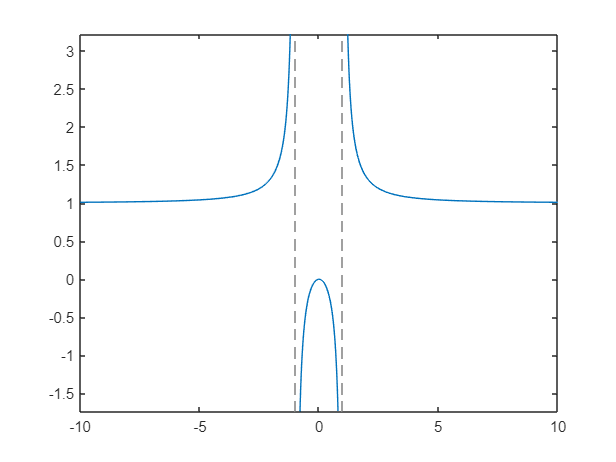

clear

f = @(x) x.^2 ./ (x.^2 - 1);

fplot(f, [-10, 10])

clear
syms f(x)

f = x^2 / (x^2 - 1)

$$f = \frac{x^{2}}{x^{2}-1}$$

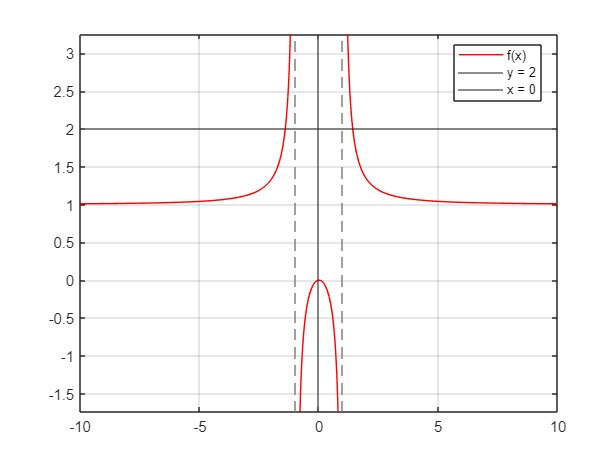

fplot(f, [-10, 10], 'r', 'DisplayName', 'f(x)')
yline(2, 'DisplayName', 'y = 2')
xline(0, 'DisplayName', 'x = 0')
grid on
legend('Location', 'best')

clear
syms f(x)

f(x) = cos(x);
f = matlabFunction(f);

help bisect

  Entrada - f es la funcion introducida con @
 	      - a y b son los extremos izquierdo y derecho
 	      - delta es la tolerancia
  Salida  - c es el cero
 	      - yc = f(c)
  	      - err es el error estimado para  c



x0 = bisect(f, 1, 2, 1e-15, 100)

k = 50

x0 = 1.5708

clear
format rat

A = gallery('tridiag', 10, 1, 4, -3); A = full(A)

A =        4             -3              0              0              0              0              0              0              0              0       
       1              4             -3              0              0              0              0              0              0              0       
       0              1              4             -3              0              0              0              0              0              0       
       0              0              1              4             -3              0              0              0              0              0       
       0              0              0              1              4             -3              0              0              0              0       
       0              0              0              0              1              4             -3              0              0              0       
       0              0              0              0              0              1       

B = A * ones(10, 1)

B =        1       
       2       
       2       
       2       
       2       
       2       
       2       
       2       
       2       
       5       


X = ones(10, 1);
P = zeros(size(B))

P =        0       
       0       
       0       
       0       
       0       
       0       
       0       
       0       
       0       
       0       


X0 = gseid(A, B, P, 1e-3, 100)

k =       26       


err =       54/17617 


relerr =       37/38173 


X0 =     1240/1239  
    1340/1341  
    1993/1992  
    3438/3439  
    6568/6567  
   13654/13655 
   30919/30918 
   77483/77484 
  225659/225658
  902632/902633


[TJ, TS] = Jac_GS(A)

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ =      290/349   


ratioTGS =     2688/3893  


ratioTw =     2688/3893  


TJ =        0              3/4            0              0              0              0              0              0              0              0       
      -1/4            0              3/4            0              0              0              0              0              0              0       
       0             -1/4            0              3/4            0              0              0              0              0              0       
       0              0             -1/4            0              3/4            0              0              0              0              0       
       0              0              0             -1/4            0              3/4            0              0              0              0       
       0              0              0              0             -1/4            0              3/4            0              0              0       
       0              0              0              0              0             -1/4    

TS =        0              3/4            0              0              0              0              0              0              0              0       
       0             -3/16           3/4            0              0              0              0              0              0              0       
       0              3/64          -3/16           3/4            0              0              0              0              0              0       
       0             -3/256          3/64          -3/16           3/4            0              0              0              0              0       
       0              3/1024        -3/256          3/64          -3/16           3/4            0              0              0              0       
       0             -3/4096         3/1024        -3/256          3/64          -3/16           3/4            0              0              0       
       0              3/16384       -3/4096         3/1024        -3/256          3/64   

norm(TJ), norm(TS, 1)

ans =      563/579   


ans =        1       


edd(A)

La matriz no es e.d.d.

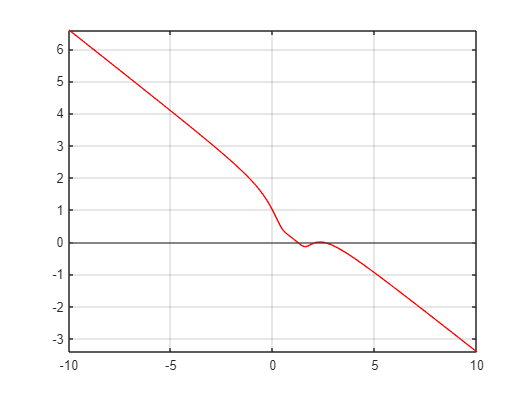

clear
syms f(x)

f(x) = exp(-1 / (x - 1)^2) -x / 2 + .6;
fplot(f, [-10,10], 'r')
yline(0)
grid on